# Practica 4. Convolucion: Metodo Gráfico

- Utilice Matlab para calcular y graficar la convolucion de las siguientes secuencias:


$$x(n) = \left( \frac{4}{5}\right)^{n}\left[ u(n)-u(n-6)\right]     $$
                                                
$$h(n) = u(n)-u(n-11)     
$$


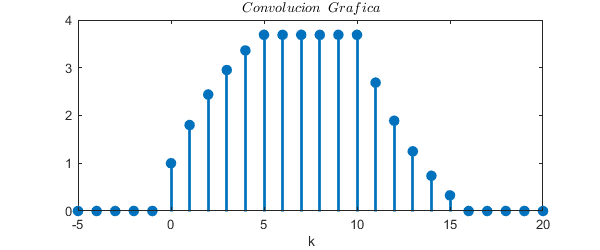

escalon = @(n) n>=0;
n=-5:10;
figure('Position',[500 400 600 250])
y = conv((4/5).^n.*(escalon(n)-escalon(n-6)),escalon(n)-escalon(n-11));
n = -10:20;
stem(n,y,'filled','LineWidth',2)
title('$ Convolucion\hspace{.2cm}Grafica $','Interpreter','latex')
xlabel('k')
xlim([-5,20]);

y = sym(y(11:26))

$$y = \left(\begin{array}{cccccccccccccccc} 1 & \frac{9}{5} & \frac{61}{25} & \frac{369}{125} & \frac{2101}{625} & \frac{11529}{3125} & \frac{11529}{3125} & \frac{11529}{3125} & \frac{11529}{3125} & \frac{11529}{3125} & \frac{11529}{3125} & \frac{8404}{3125} & \frac{5904}{3125} & \frac{3904}{3125} & \frac{2304}{3125} & \frac{1024}{3125} \end{array}\right)$$

2. Utilice Matlab para crear una animacion que muestre el metodo grafico para calcular la convolucion de las secuencias del inciso anterior

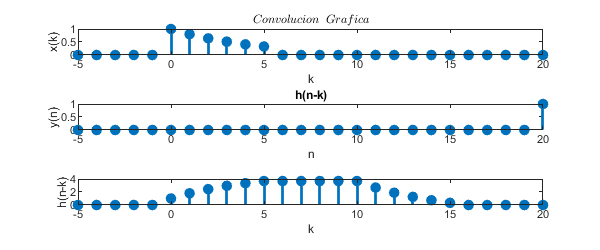

figure('Position',[500 400 600 250])
escalon = @(n) n>=0;
n = -15:20;
x1 = @(n) (4/5).^n.*(escalon(n)-escalon(n-6));
h1 = @(n) escalon(n)-escalon(n-11);
yconv = zeros(1,36);
figure('Position',[500 400 600 250])
for k = n
   
    y =@(n) conv(x1(k),h1(n-k));
    yconv =+ yconv + y(n) ;
    subplot(311)
    stem(n,x1(n),'filled','LineWidth',2)
    title('$ Convolucion\hspace{.2cm}Grafica $','Interpreter','latex')
    xlabel('k')
    ylabel('x(k)')
    xlim([-5,20]);
    
    subplot(313)
    stem(n,yconv,'filled','LineWidth',2)
    xlabel('k')
    ylabel('h(n-k)')
    xlim([-5,20]);
    drawnow
    pause(0.1)
    
    subplot(312)
    stem(n,h1(n-k),'filled','LineWidth',2)
    title('h(n-k)')
    xlabel('n')
    ylabel('y(n)'),
    xlim([-5,20]);
    drawnow
    pause(0.1)
end

Grafique cada uno de los casos analizados en el metodo de convolucion grafica.

Caso (i) $n<0$

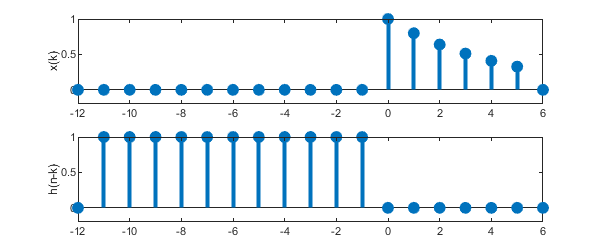

figure('Position',[500 400 600 250])
n=-12:6;
escalon = @(n) n>=0;
x = (4/5).^n.*(escalon(n)-escalon(n-6));
subplot(211)
stem(n,x,'filled','LineWidth',3)
ylabel('x(k)')
ylim([-.2 1])

subplot(212)
h = zeros(1,33);
n=-12:20;
h = escalon(n+11)-escalon(n);
stem(n,h,'filled','LineWidth',3)
ylabel('h(n-k)')
xlim([-12 6]);
ylim([-.2 1])

Caso (ii) $0\le n\le 5$

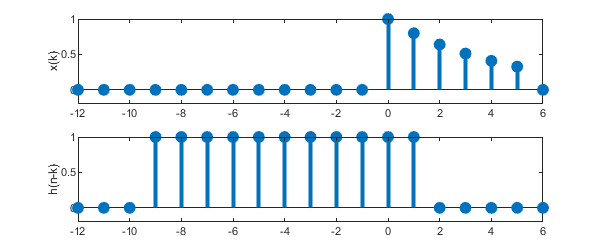

figure('Position',[500 400 600 250])
n=-12:6;
escalon = @(n) n>=0;
x = (4/5).^n.*(escalon(n)-escalon(n-6));
subplot(211)
stem(n,x,'filled','LineWidth',3)
ylabel('x(k)')
ylim([-.2 1])

subplot(212)
h = zeros(1,33);
n=-12:20;
h = escalon(n+9)-escalon(n-2);
stem(n,h,'filled','LineWidth',3)
ylabel('h(n-k)')
xlim([-12 6]);
ylim([-.2 1])

Caso (iii) $6\le n\le 10$

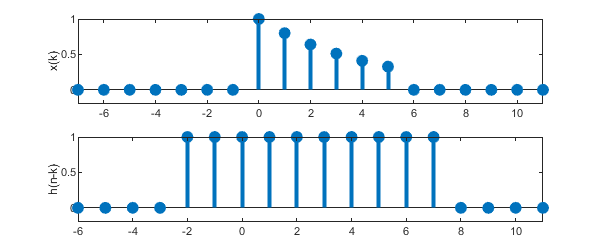

figure('Position',[500 400 600 250])
n=-12:11;
escalon = @(n) n>=0;
x = zeros(20);
x = (4/5).^n.*(escalon(n)-escalon(n-6));
subplot(211)
stem(n,x,'filled','LineWidth',3)
ylabel('x(k)')
xlim([-7 11]);
ylim([-.2 1])

subplot(212)
h = zeros(1,33);
n=-12:20;
h = escalon(n+2)-escalon(n-8);
stem(n,h,'filled','LineWidth',3)
ylabel('h(n-k)')
xlim([-6 11]);
ylim([-.2 1])

Caso (iv) $11\le n\le 15$

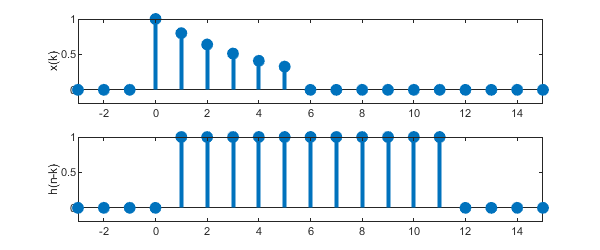

figure('Position',[500 400 600 250])
n=-3:15;
escalon = @(n) n>=0;
x = zeros(20);
x = (4/5).^n.*(escalon(n)-escalon(n-6));
subplot(211)
stem(n,x,'filled','LineWidth',3)
ylabel('x(k)')
xlim([-3 15]);
ylim([-.2 1])

subplot(212)
h = zeros(1,33);
n=-12:20;
h = escalon(n-1)-escalon(n-12);
stem(n,h,'filled','LineWidth',3)
ylabel('h(n-k)')
xlim([-3 15]);
ylim([-.2 1])

Caso (v) $n\ge 16$

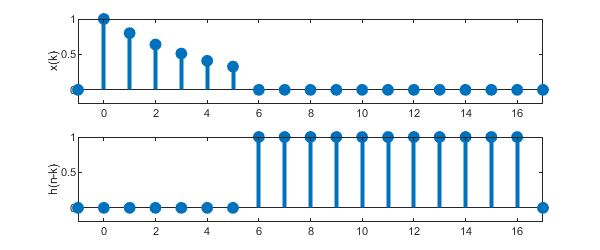

figure('Position',[500 400 600 250])
n=-3:17;
escalon = @(n) n>=0;
x = zeros(20);
x = (4/5).^n.*(escalon(n)-escalon(n-6));
subplot(211)
stem(n,x,'filled','LineWidth',3)
ylabel('x(k)')
xlim([-1 17]);
ylim([-.2 1])

subplot(212)
h = zeros(1,33);
n=-12:20;
h = escalon(n-6)-escalon(n-17);
stem(n,h,'filled','LineWidth',3)
ylabel('h(n-k)')
xlim([-1 17]);
ylim([-.2 1])

   Anexo de Codigo 

%Ejercicio 1

escalon = @(n) n>=0;

n=-5:10;

figure('Position',[500 400 600 250])

y = conv((4/5).^n.*(escalon(n)-escalon(n-6)),escalon(n)-escalon(n-11));

n = -10:20;

stem(n,y,'filled','LineWidth',2)

title('$ Convolucion\hspace{.2cm}Grafica $','Interpreter','latex')

xlabel('k')

xlim([-5,20]);

y = sym(y(11:26))

%Ejercicio 2. simulacion

figure('Position',[500 400 600 250])

escalon = @(n) n>=0;

n = -15:20;

x1 = @(n) (4/5).^n.*(escalon(n)-escalon(n-6));

h1 = @(n) escalon(n)-escalon(n-11);

yconv = zeros(1,36);

figure('Position',[500 400 600 250])

for k = n

    y =@(n) conv(x1(k),h1(n-k));

    yconv =+ yconv + y(n) ;

    subplot(311)

    stem(n,x1(n),'filled','LineWidth',2)

    title('$ Convolucion\hspace{.2cm}Grafica $','Interpreter','latex')

    xlabel('k')

    ylabel('x(k)')

    xlim([-5,20]);

    subplot(313)

    stem(n,yconv,'filled','LineWidth',2)

    xlabel('k')

    ylabel('h(n-k)')

    xlim([-5,20]);

    drawnow

    pause(0.1)

    subplot(312)

    stem(n,h1(n-k),'filled','LineWidth',2)

    title('h(n-k)')

    xlabel('n')

    ylabel('y(n)'),

    xlim([-5,20]);

    drawnow

    pause(0.1)

end

%Ejercicio 2. casos de la convolucion

%Caso 1

figure('Position',[500 400 600 250])

n=-12:6;

escalon = @(n) n>=0;

x = (4/5).^n.*(escalon(n)-escalon(n-6));

subplot(211)

stem(n,x,'filled','LineWidth',3)

ylabel('x(k)')

ylim([-.2 1])

subplot(212)

h = zeros(1,33);

n=-12:20;

h = escalon(n+11)-escalon(n);

stem(n,h,'filled','LineWidth',3)

ylabel('h(n-k)')

xlim([-12 6]);

ylim([-.2 1])

%Caso 2

figure('Position',[500 400 600 250])

n=-12:6;

escalon = @(n) n>=0;

x = (4/5).^n.*(escalon(n)-escalon(n-6));

subplot(211)

stem(n,x,'filled','LineWidth',3)

ylabel('x(k)')

ylim([-.2 1])

subplot(212)

h = zeros(1,33);

n=-12:20;

h = escalon(n+9)-escalon(n-2);

stem(n,h,'filled','LineWidth',3)

ylabel('h(n-k)')

xlim([-12 6]);

ylim([-.2 1])

%Caso 3

figure('Position',[500 400 600 250])

n=-12:11;

escalon = @(n) n>=0;

x = zeros(20);

x = (4/5).^n.*(escalon(n)-escalon(n-6));

subplot(211)

stem(n,x,'filled','LineWidth',3)

ylabel('x(k)')

xlim([-7 11]);

ylim([-.2 1])

subplot(212)

h = zeros(1,33);

n=-12:20;

h = escalon(n+2)-escalon(n-8);

stem(n,h,'filled','LineWidth',3)

ylabel('h(n-k)')

xlim([-6 11]);

ylim([-.2 1])

%Caso 4

figure('Position',[500 400 600 250])

n=-3:15;

escalon = @(n) n>=0;

x = zeros(20);

x = (4/5).^n.*(escalon(n)-escalon(n-6));

subplot(211)

stem(n,x,'filled','LineWidth',3)

ylabel('x(k)')

xlim([-3 15]);

ylim([-.2 1])

subplot(212)

h = zeros(1,33);

n=-12:20;

h = escalon(n-1)-escalon(n-12);

stem(n,h,'filled','LineWidth',3)

ylabel('h(n-k)')

xlim([-3 15]);

ylim([-.2 1])

%Caso 5

figure('Position',[500 400 600 250])

n=-3:17;

escalon = @(n) n>=0;

x = zeros(20);

x = (4/5).^n.*(escalon(n)-escalon(n-6));

subplot(211)

stem(n,x,'filled','LineWidth',3)

ylabel('x(k)')

xlim([-1 17]);

ylim([-.2 1])

subplot(212)

h = zeros(1,33);

n=-12:20;

h = escalon(n-6)-escalon(n-17);

stem(n,h,'filled','LineWidth',3)

ylabel('h(n-k)')

xlim([-1 17]);

ylim([-.2 1])